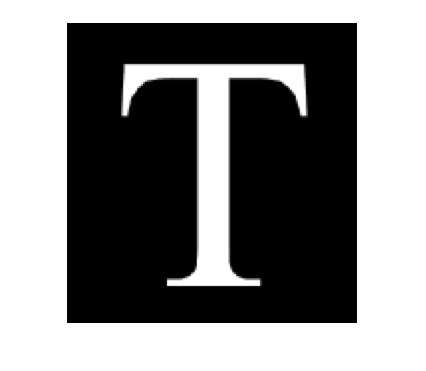

I = imread("imageT.png");
G = rgb2gray(I);
imshow(G);

Escalado

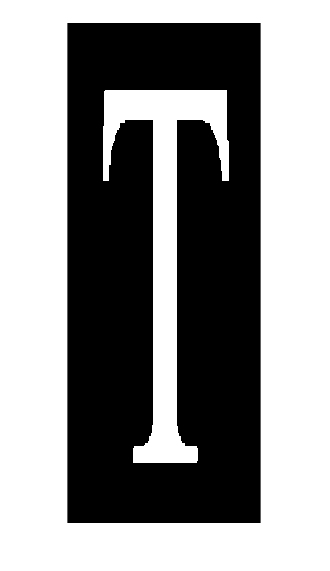

Cx = 5; Cy=2;
[x, y] = size(G);
Img_Scale = zeros(x*Cx, y*Cy);
scaling = [Cx 0 0;
    0 Cy 0;
    0 0 1];

for i=1:x
    for j=1:y
        coord = [i j 1] * scaling;
        Img_Scale((coord(1)-Cx+1):coord(1), (coord(2)-Cy+1):coord(2)) = G(i,j);
    end
end
imshow(Img_Scale);

Identidad

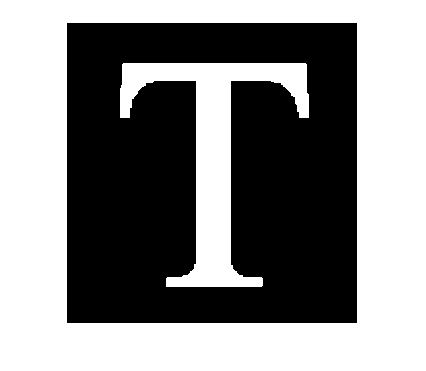

% Cx = 5; Cy=2;
[x, y] = size(G);
Img_Identidad = zeros(x, y);
identidad = [1 0 0;
    0 1 0;
    0 0 1];

for i=1:x
    for j=1:y
        coord = [i j 1] * identidad;
        Img_Identidad(coord(1), coord(2)) = G(i,j);
    end
end
imshow(Img_Identidad);

Traslación

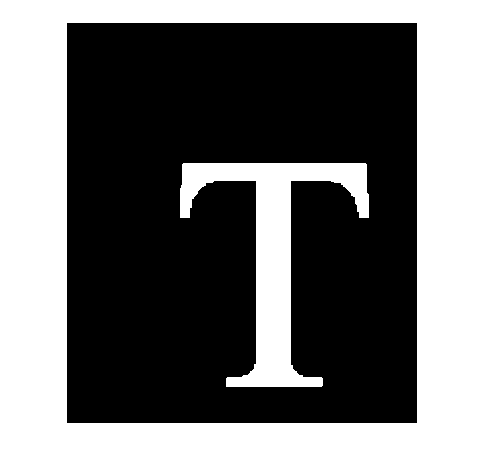

tx = 100; ty=60;
[x, y] = size(G);
Img_Traslation = zeros(x+tx, y+ty);
traslation = [1 0 0;
    0 1 0;
    tx ty 1];

for i=1:x
    for j=1:y
        coord = [i j 1] * traslation;
        Img_Traslation(coord(1), coord(2)) = G(i,j);
    end
end
imshow(Img_Traslation);

Rotacion

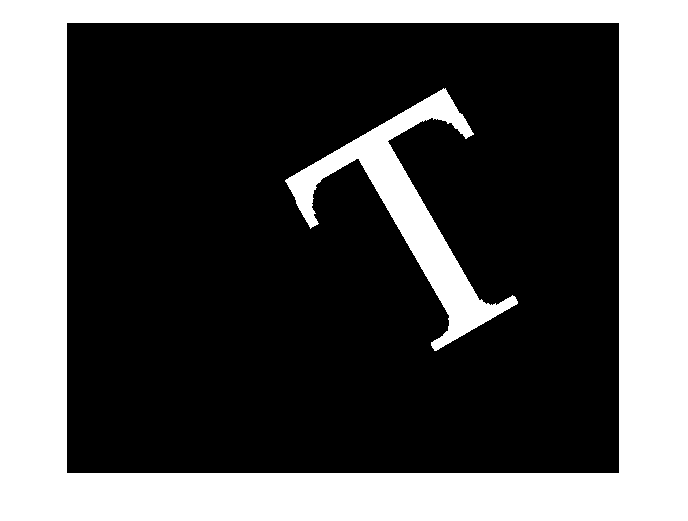

tx = 150; ty = 150;
tetha = pi/6;
seno = sin(tetha);
coseno = cos(tetha);
[x, y] = size(G);
Img_Rotacion = zeros(x+tx, y+ty);
rotacion = [coseno seno 0;
    -seno coseno 0;
    tx ty 1];
for i=1:x
    for j=1:y
        coord = ([i j 1] * rotacion);
        Img_Rotacion(round(coord(1)):round(coord(1))+1, round(coord(2)):round(coord(2))+1) = G(i,j);
    end
end
imshow(Img_Rotacion);

Distorisión Horizontal

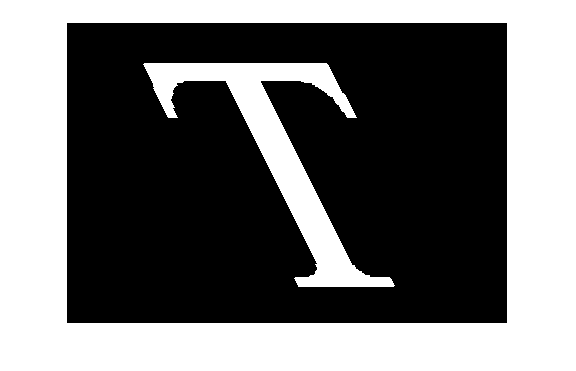

Sh=0.5;
[x, y] = size(G);
Img_DHorizontal = zeros(x, y);
dHorizontal = [1 Sh 0;
    0 1 0;
    0 0 1];

for i=1:x
    for j=1:y
        coord = [i j 1] * dHorizontal;
        Img_DHorizontal(round(coord(1)), round(coord(2))) = G(i,j);
    end
end
imshow(Img_DHorizontal);

Distorisión Vertical

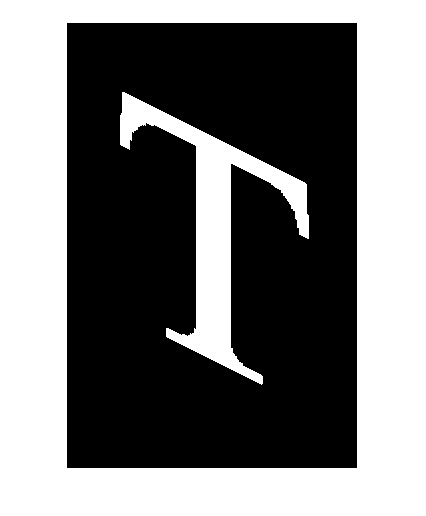

Sv=0.5;
[x, y] = size(G);
Img_DVertical = zeros(x, y);
dVertical = [1 0 0;
    Sv 1 0;
    0 0 1];

for i=1:x
    for j=1:y
        coord = [i j 1] * dVertical;
        Img_DVertical(round(coord(1)), round(coord(2))) = G(i,j);
    end
end
imshow(Img_DVertical);

Corrección Gamma

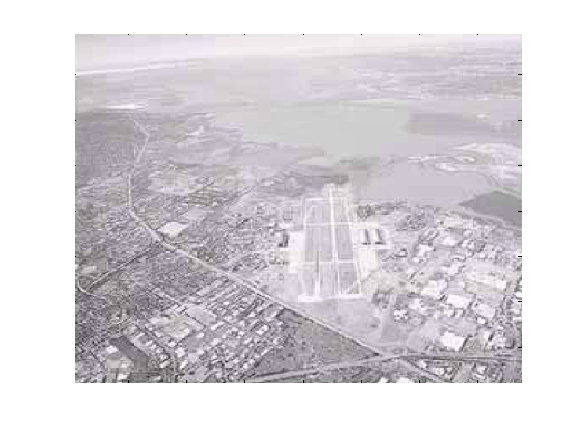

I = imread("aerea.png");
% G = rgb2gray(I);
imshow(I);

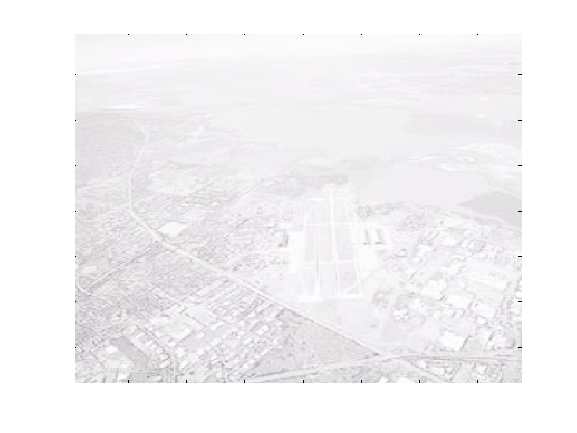

gamma1 = 0.04;
gamma2 = 1;
gamma3 = 2.5;
% nI = double(I).^gamma ;
L1=im2uint8(mat2gray(double(I).^gamma1));
L2=im2uint8(mat2gray(double(I).^gamma2));
L3=im2uint8(mat2gray(double(I).^gamma3));
figure;
imshow(L1);

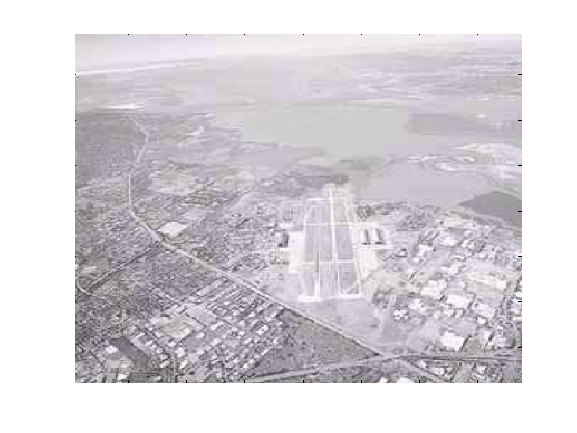

figure;
imshow(L2);

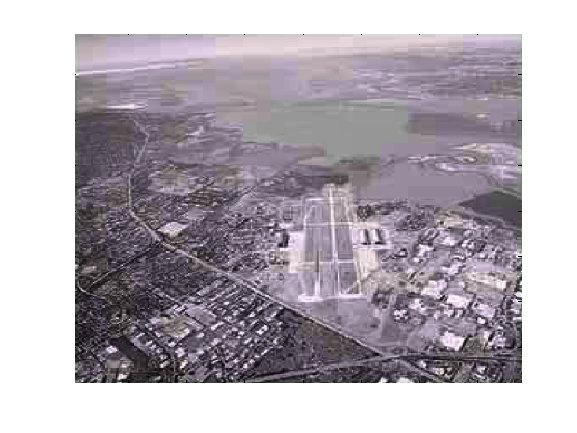

figure;
imshow(L3);

Histogramas

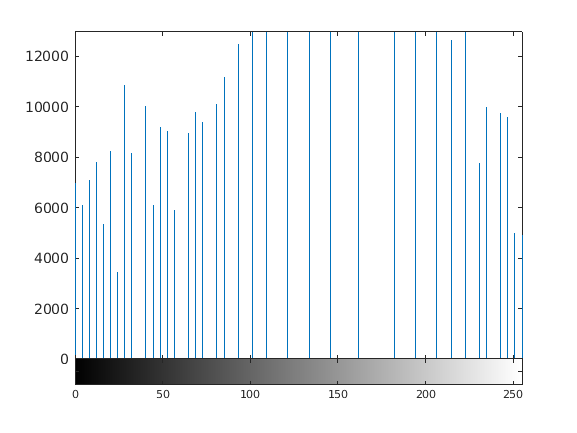

H1 = histeq(L1);
imhist(H1);

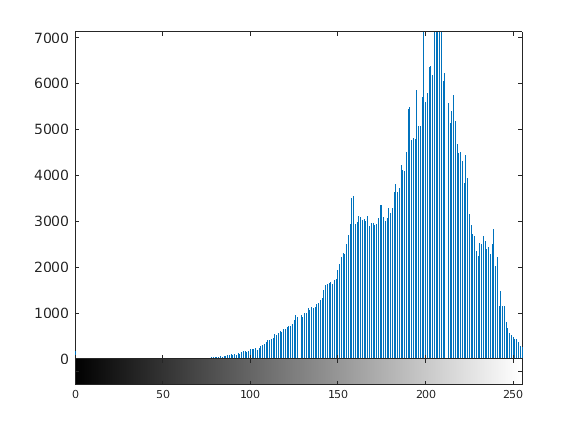

H2 = histeq(L2);
imhist(L2);

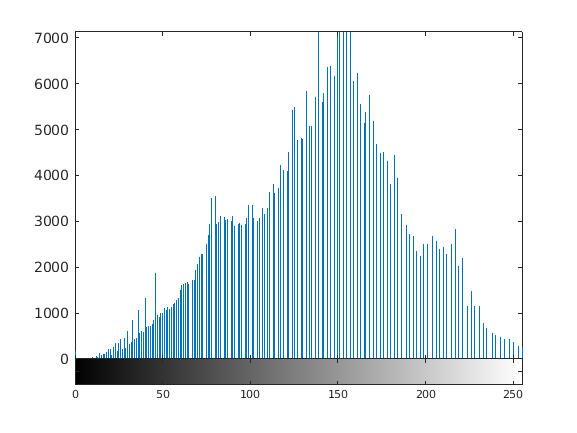

H3 = histeq(L3);
imhist(L3);